# Finding a 2D SSM for a von Kármán beam

This is an example of how to reconstruct a slow 2D SSM of a mechanical system using synthetic measurements of a scalar quantity. In this example, we measure the end tip displacement of a von Kármán beam. [1]

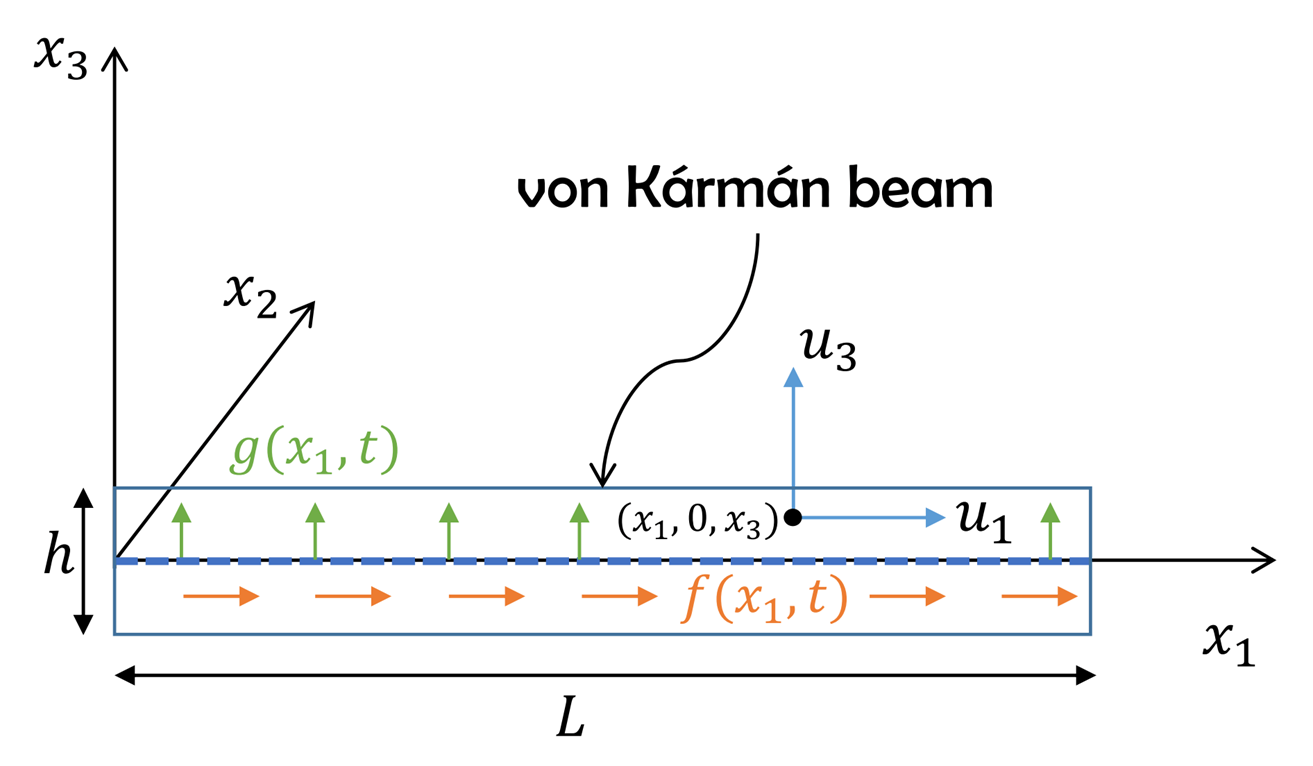

[1] Jain, S., Tiso, P. & Haller, G. (2017). Exact Nonlinear Model Reduction for a von Karman beam: Slow-Fast Decomposition and Spectral Submanifolds. Journal of Sound and Vibration. 423. 10.1016/j.jsv.2018.01.049. 

clearvars
close all

## Example setup

The $N$-degree of freedom dynamical system is of the form


$$\mathbf{M\ddot{q}} + \mathbf{C\dot{q}} + \mathbf{Kq} + \mathbf{f}(\mathbf{q},\mathbf{\dot{q}}) = \mathbf{0}$$


where $\mathbf{f}=\mathcal{O}(|\mathbf{q}|^2,|\mathbf{\dot{q}}|^2,|\mathbf{q}||\mathbf{\dot{q}}|)$ represents the nonlinearities and $\mathbf{M}$, $\mathbf{C}$, and $\mathbf{K}$ are the $N\times N$ mass, stiffness, and damping matrices, respectively.

We rewrite the system in first-order form as


$$\mathbf{\dot{x}} = \mathbf{A}\mathbf{x} + \mathbf{G}(\mathbf{x}) = \mathbf{F}(\mathbf{x})$$


with

$\mathbf{x}=\left[\begin{array}{c}\mathbf{q}\\\dot{\mathbf{q}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}\mathbf{0} 
& \mathbf{I}\\-\mathbf{M}^{-1}\mathbf{K} & -\mathbf{M}^{-1}\mathbf{C} \end{array}\right],\quad\mathbf{G}(\mathbf{x})=\left[\begin{array}{c} \mathbf{0} \\ -\mathbf{M}^{-1}\mathbf{f}(\mathbf{x})\end{array}\right]$.

nElements = 2;
E       = 70e9;   % Young's modulus
rho     = 2700;   % density
nu      = 0.3;    % nu
kappa   = 3e6;    % linear damping
l       = 1;      % beam length
h       = 20e-3;  % height
b       = 50e-3;  % width

[M,C,K,fnl] = von_karman_model(nElements, E, rho, nu, kappa, l, h, b);

Building FE model
Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem
Getting nonlinearity coefficients
Assembling Tensors
Total time spent on model assembly = 00:00:00


n = size(M,1);    % mechanical dofs (axial def, transverse def, angle)
[F, lambda] = functionFromTensors(M, C, K, fnl);

## Generation of Synthetic Data

Having set up the dynamics of the problem, we now move on to generate synthetic data, which will be used to fit a parametrisation of the manifold. We will divide the data into a training set, for model fitting, and a test set, for validation. In this case we will use one trajectory as the training set and another one as the test set.

nTraj = 2;
indTest = [1];
indTrain = setdiff(1:nTraj, indTest);

We now set the initial conditions for the trajectories. Our test set trajectory is initialized by applying a point load at the beam tip, which is removed at the start of the simulation. For the training trajectory, we use a different point load. We expect the trajectories to eventually converge onto a slow 2D manifold, which will be identified and used to reduce the system dynamics.

loadvector = zeros(n,nTraj);
loadvector(n-1,1) = 700; % point load, [N]
loadvector(n-1,2) = 800; % point load, [N]
w0 = -K\loadvector(:,1); % linear initial guess
options = optimoptions('fsolve', 'MaxFunctionEvaluations', 200*n, 'Display', 'off');
for iLoad = 1:nTraj
    f_eq = @(w)([zeros(n) M]*F(0,[w; zeros(n,1)]) + loadvector(:,iLoad));
    [w0, ~, exitflag, output] = fsolve(f_eq, w0, options);
    if exitflag <= 0
        error('Warning: No solution found for loading configuration')
    end
    IC(:,iLoad) = [w0; zeros(n,1)];
end

The data is generated by time-integration of the right-hand side of the system. In this case we are observing the end tip displacement, so the `observable` function is selected to save only the transverse displacement of the leftmost element. We also make sure that the data is sampled with a sufficiently high frequency.

observable = @(x) x(n-1,:);
tEnd = 10;
nSamp = fix(50 * tEnd * abs(imag(lambda(1))) / (2*pi));
dt = tEnd/(nSamp-1);
tic
xData = integrateTrajectories(F, observable, tEnd, nSamp, nTraj, IC);

simulating trajectory 1 of 2...
simulating trajectory 2 of 2...


toc

Elapsed time is 22.768341 seconds.


## Delay embedding

Now we arrange the scalar measurements in an observable space of dimension at least $2m+1$, with $m$ the dimension of the manifold. This guarantees that the manifold from the full state space can be embedded in the observable space. The dimensionality of the observable space can be further expanded with the parameter `overEmbed` to facilitate recognition of the manifold from data.

We form a multi-dimensional observable by stacking $d$ subsequent scalar measurements $x$ in a vector $y$, and we will later use the trajectories in this augmented space for the manifold fitting.


$$\left[
\begin{array}{c}
y_{1} \\ \vdots \\ y_{i+1} \\ \vdots \\ y_{d+1}
\end{array} 
\right] = 
\left[
\begin{array}{c}
x(t^k) \\ \vdots \\ x(t^k+i\Delta t) \\ \vdots \\ x(t^k+d\Delta t)
\end{array} 
\right]$$


The total number of embedded coordinates is $2m+1 + \texttt{overEmbed}$.

SSMDim = 2;
overEmbed = 3;
yData = coordinates_embedding(xData, SSMDim, 'OverEmbedding', overEmbed);

The 8 embedding coordinates consist of the measured state and its 7 time-delayed measurements.


## Data filtering

We need to make sure that the data that we use to identify the slow manifold lies close to it. We can do this by plotting a spectrogram of the beam tip displacement $u$. In general, there may be many vibratory modes present at first, but the faster ones quickly die out.

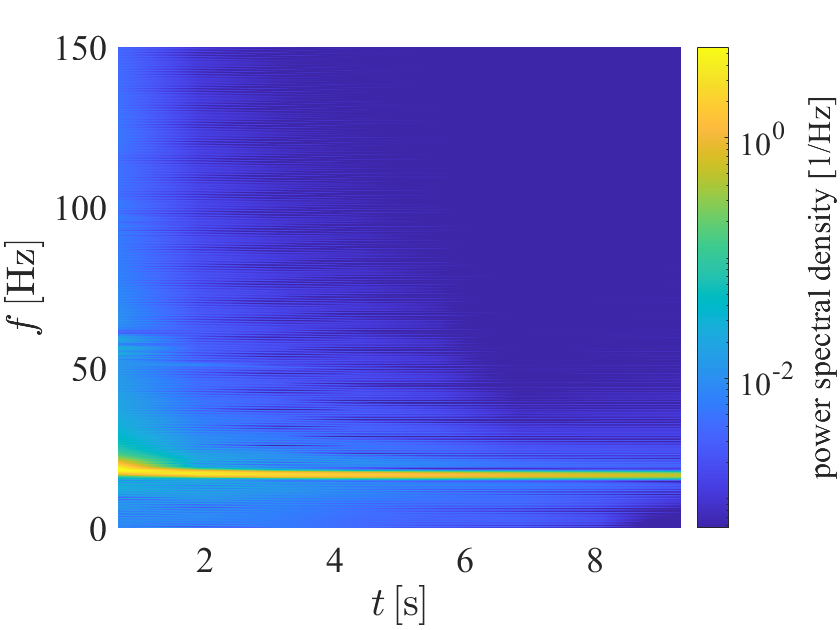

showSpectrogram(yData(indTrain,:), 1);
ylim([0,150])

We plot the tip displacement  over time for closer inspection. 

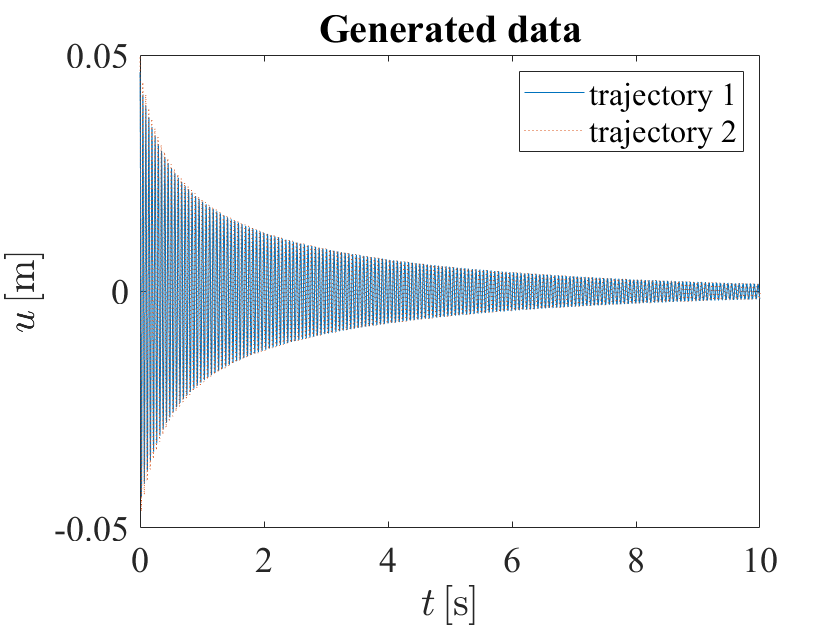

plot(xData{1,1}, xData{1,2}, xData{2,1}, xData{2,2}, ':');
xlabel('$t \, [$s$]$','Interpreter','latex'); ylabel('$u \, [$m$]$','Interpreter','latex'); 
legend({'trajectory 1', 'trajectory 2'})
set(gca,'fontname', 'times'); set(gca,'fontsize', 18); title('Generated data')

Next, we use the information from the spectrogram and plot to remove the first part of the training data. After the first few oscillations have passed, there is one dominant mode left in the frequency spectrum. In this case, faster modes die out very quickly, so we can use almost all of the data. We must however remove the first transient to fulfill the assumption that trajectories lie close to the SSM. We keep only the time interval `sliceInt`.

sliceInt = [0.1, tEnd];
yDataTrunc = sliceTrajectories(yData, sliceInt);

## Datadriven manifold fitting

The measured trajectories are assumed to lie close to a two-dimensional manifold that is tangent at the origin to the eigenspace corresponding to the slowest pair of eigenvalues. We now want to fit a polynomial of order $M$ to the data points to approximate the manifold. Here we use a graph style parametrization, meaning that the manifold is parametrized using coordinates in the computed eigenspace $V_e$. This excludes the possibility of folds on the manifold (however, if necessary we may circumvent this problem by increasing the dimensionality of the observed space). 

 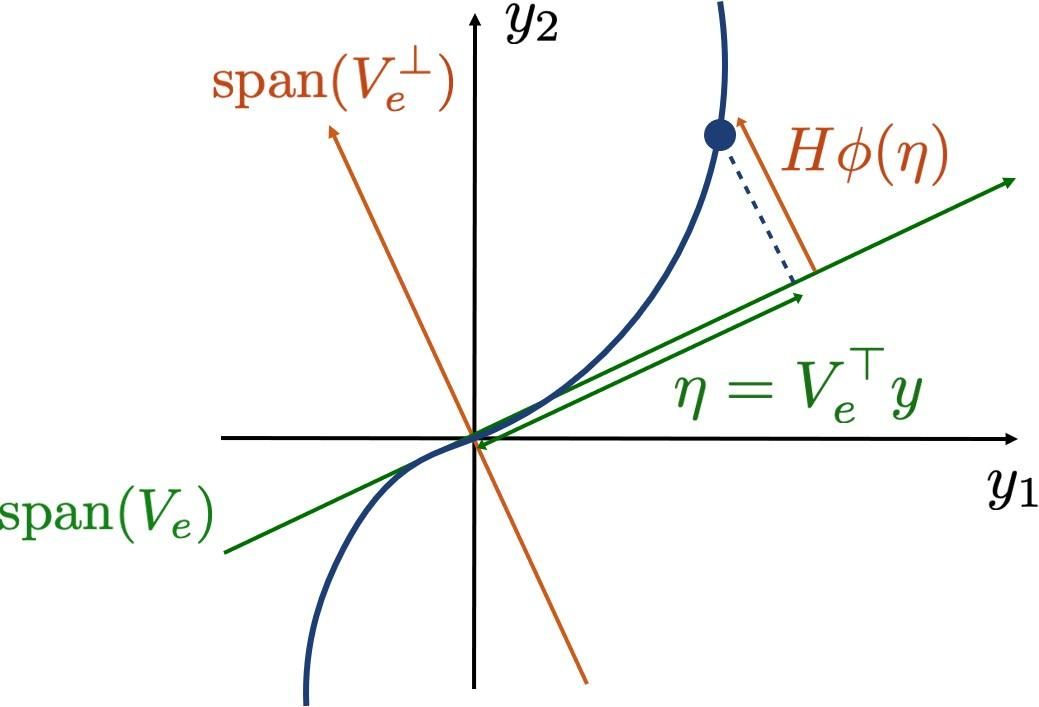

We seek the $2N\times m_M$ polynomial coefficient matrix $H$ of the manifold on the form

$y = V_e V_e^\top y + H \phi_{m,2:M}(V_e^\top y) $,

where the function $\phi_{m,2:M}(q)$ computes a vector of all $m_M$ monomials from orders 2 up to $M$ of an $m$-vector $q$. This optimization problem amounts to minimizing a cost function computed from the measured data $y_k$,


$$C_r(V_e,H) = \sum_{k=1}^N ||y_k - V_eV_e^\top y_k - H\phi_{m,2:M}(V_e^\top y_k) ||$$


to find $H$ and the $2N\times 2$ eigenspace matrix $V_e$, under the constraints that $V_e^\top H=0$ and $V_e^\top V_e = I$. The minimization is performed with the Matlab function `fmincon` in `IMparametrization`.

SSMOrder = 3;
[V, SSMFunction, mfdInfo] = IMparametrization(yDataTrunc(indTrain,:), SSMDim, SSMOrder);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    1.594415e-09    2.220e-16    5.755e-08

Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<

## Plot and validation

Now that we have computed the eigenspace of the manifold, we pass to the reduced coordinates $y$ by projecting all trajectories onto the eigenspace. 

etaData = getProjectedTrajs(yData, V);
etaDataTrunc = getProjectedTrajs(yDataTrunc, V);

We plot the test and training set trajectories projected onto the plane. After all initial transients die out, the trajectories seem to be confined to a slowly decaying oscillating eigenmode. This is the data we will use to train our reduced order model for the dynamics. In these coordinates, the initial transient that we removed is visible as irregular high-frequency oscillations in the first revolution.

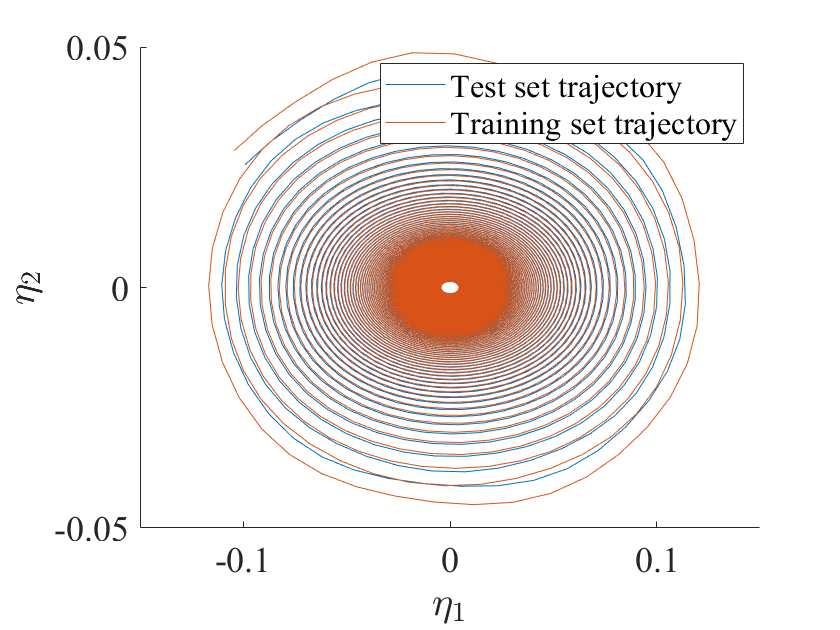

plotReducedCoords(etaData);
legend({'Test set trajectory', 'Training set trajectory'})

Furthermore, we draw the end tip component of the manifold shape along with the trajectory from the training set. 

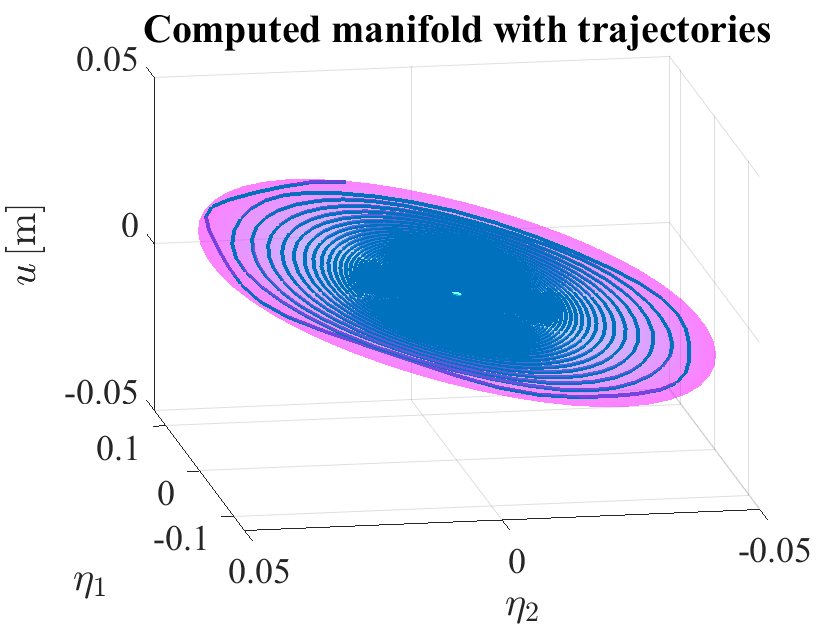

plotSSMWithTrajectories(yData(indTrain,:), SSMFunction, 1, V, 10, 'SSMDimension', SSMDim)
view(-100,20); zlabel('$u \, [$m$]$','Interpreter','latex')

## Reduced order model

We compute a model for the reduced dynamics with the truncated training data projected onto the manifold. The function `IMdynamics_flow` fits a polynomial map


$$\dot{\eta} = W_r \phi(\eta)$$


where $\phi(\eta)$ again computes a vector of all monomials of $\eta$, and $W_r$ is a matrix of polynomial coefficients. 

We are also specifying that we want the reduced dynamics on a normal form, and seek the Taylor expansion of a map $N$ fulfilling


$$\dot{z} = N(z) \approx Dz + W_n\phi(z)$$


with $D$ a diagonal matrix and $W_n$ containing coefficients for the near-resonant nonlinear terms, after a near-identity change of coordinates


$$z = T^{-1}(\eta) \approx \eta + W_t \phi(\eta)$$


with $W_t$ containing the coefficients for the nonlinear terms of the coordinate change.

Estimation of the reduced dynamics...  Done. 
Estimation of the reduced dynamics in normal form...
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1          28.0945                          37.8
     1           2          14.0317      0.0264295             60  
     2           3          4.15249              1           21.1  
     3           4          1.35843              1           9.66  
     4           5         0.524843              1            2.3  
     5           6         0.438711              1           2.02  
     6           7         0.389381              1           1.64  
     7           8         0.335409              1           1.13  
     8           9         0.281947              1          0.747  
     9          10         0.268061              1          0.577  
    10          11         0.261145              1          0.301  
    11          12

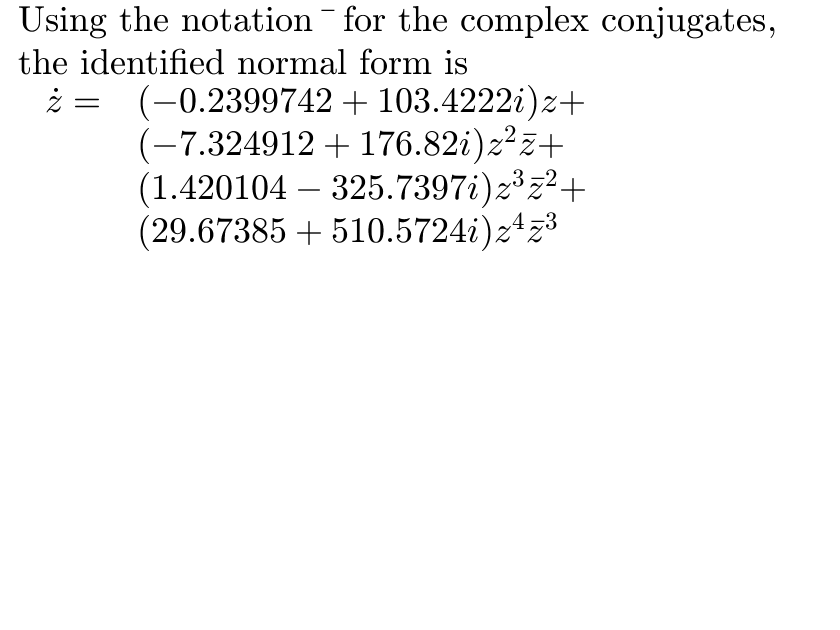

ROMOrder = 7;
[~,Tinv,N,T,NormalFormInfo] = IMdynamics_flow(etaDataTrunc(indTrain,:), 'R_PolyOrd', ROMOrder, 'style', 'normalform');

We transform the truncated initial condition of our test trajectory according to the obtained change of coordinates, and integrate our reduced order evolution rule to predict the development of the trajectory. 

zData = transformComplex(Tinv, etaDataTrunc);
[zRec, yRecNormal] = integrateFlows(N, zData, @(q) SSMFunction(T(q)));
etaRecNormal = transformComplex(T, zRec);

## Evaluation of reduced dynamics

The error RRMSE is computed as the average distance of the predicted trajectory to the measured one in the full state space.

[reducedTrajDist, fullTrajDist] = computeRecDynErrors(etaRecNormal, yRecNormal, etaDataTrunc, yDataTrunc);
RRMSE_normal = mean(fullTrajDist(indTest))

RRMSE_normal = 0.0614

We plot the true test set trajectory in the reduced coordinates and compare it to the prediction. 

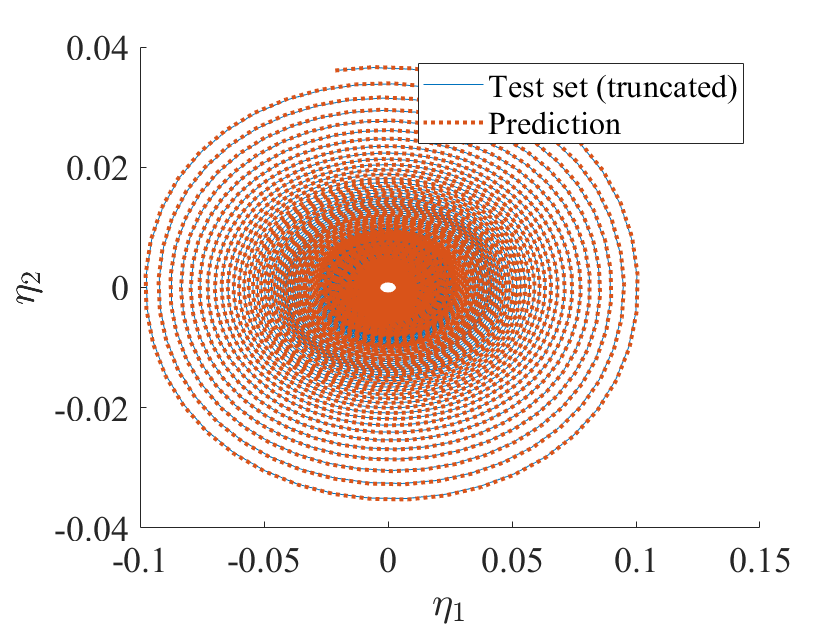

plotReducedCoords(etaDataTrunc(indTest(1),:), etaRecNormal(indTest(1),:))
legend({'Test set (truncated)', 'Prediction'})

We also plot the measured and predicted tip displacement. The reduced model seems to do well on previously unseen data, provided that it is close to the 2D manifold.

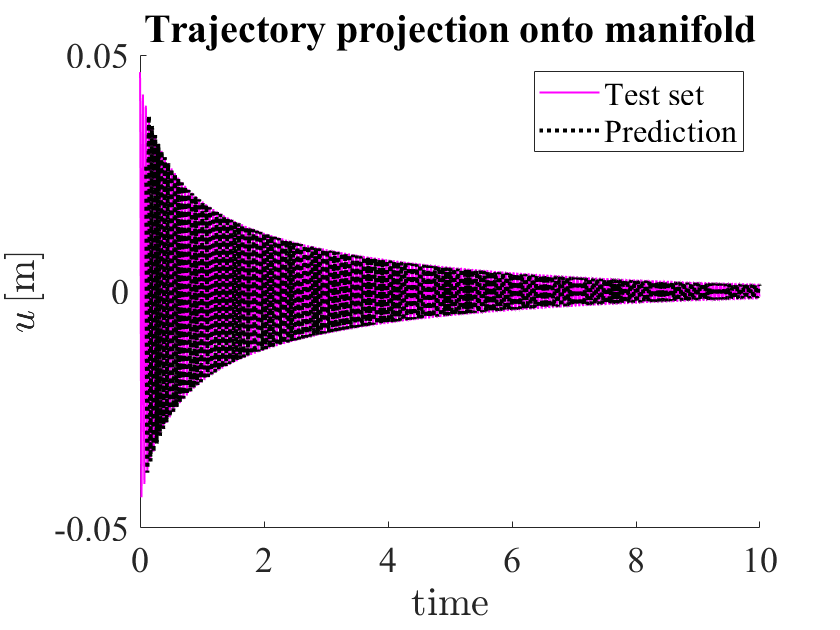

plotReconstructedTrajectory(yData(indTest(1),:), yRecNormal(indTest(1),:), 1, 'm')
legend({'Test set', 'Prediction'}); ylabel('$u \, [$m$]$','Interpreter','latex')

Finally we compare the estimated eigenvalues of the continuous evolution function to the ones computed from the linearized system. 

DSEigenvalues = lambda(1:SSMDim)

DSEigenvalues = 	1.0e+02 *

  -0.0023 - 1.0341i
  -0.0023 + 1.0341i


normalFormEigenvalues = computeEigenvaluesFlow(NormalFormInfo)

normalFormEigenvalues = 	1.0e+02 *

  -0.0024 + 1.0342i
  -0.0024 - 1.0342i


## Backbone curves

With the knowledge of the coefficients of the normal form, we extract backbone curves for the instantaneous damping and frequency.

Plotting figure with the polar normal form equations ... Done. 


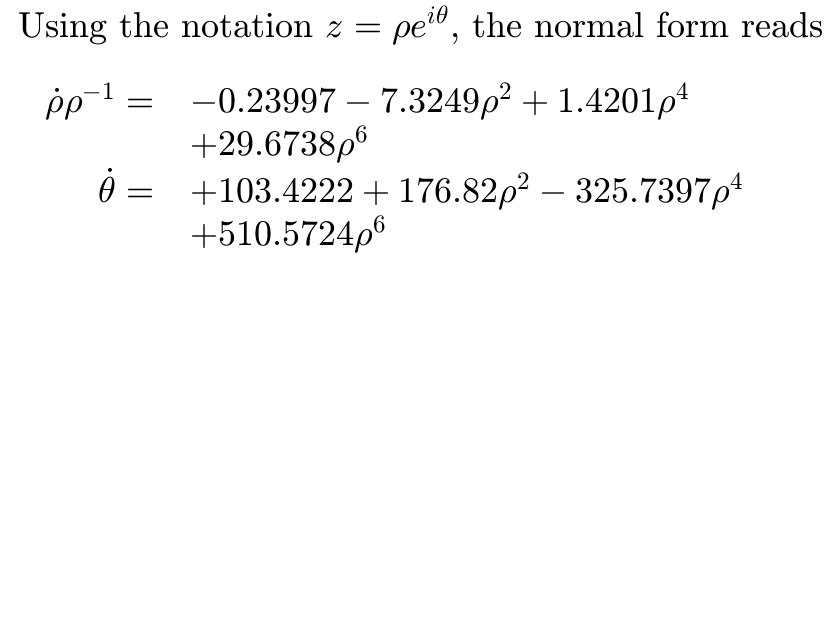

N_info = NormalFormInfo.N;
[damp, freq] = polarnormalform(N_info.coeff, N_info.exponents, N_info.phi);

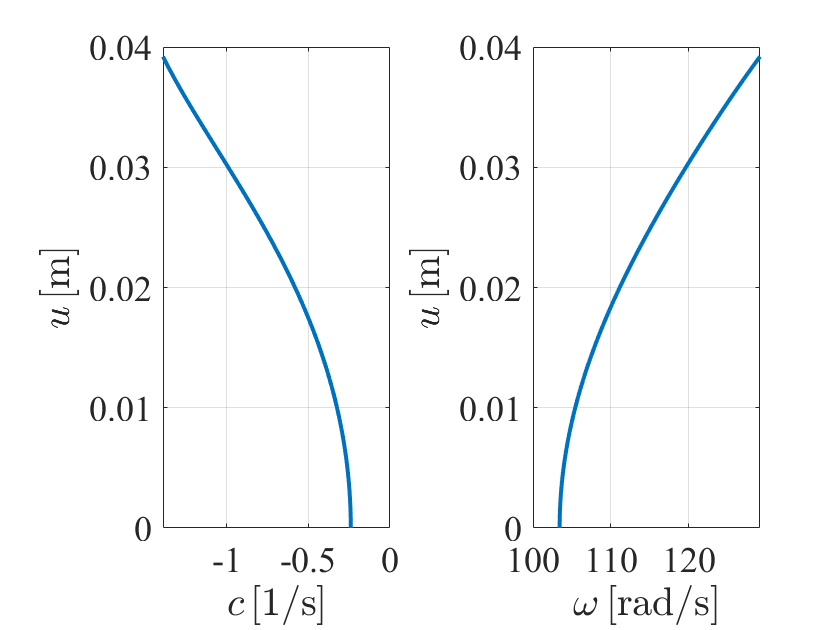

figure
maxRho = abs(zData{indTest(1),2}(1,1));
[dmp, frq, amp, rho_plot] = backbonecurves(damp, freq, SSMFunction, T, 1, maxRho);
subplot(121); ylabel('$u \, [$m$]$','Interpreter','latex')
subplot(122); ylabel('$u \, [$m$]$','Interpreter','latex')

The data-driven model can now be used for forced response predictions. We first compute forced response using the full model with SSMTool that are used, after calibration, to validate the predictions of our data-driven reduced-order model.

% Compute with SSMTool
f_full = [0.7000    1.4000    3.5000];
f_vec = loadvector(:,1)/max(abs(loadvector(:,1)));
w_span = [90 125];
FRC_full = getFRC_full(M, C, K, fnl, f_vec, f_full, n-1, w_span, ROMOrder); close all

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.215952e-03
modal damping ratio for 2 mode is 1.399821e-02
modal damping ratio for 3 mode is 4.734451e-02
modal damping ratio for 4 mode is 1.374140e-01
modal damping ratio for 5 mode is 1.758199e-01

 The first 10 eigenvalues are given as 
   1.0e+03 *

  -0.0002 + 0.1034i
  -0.0002 - 0.1034i
  -0.0091 + 0.6532i
  -0.0091 - 0.6532i
  -0.1046 + 2.2069i
  -0.1046 - 2.2069i
  -0.8812 + 6.3518i
  -0.8812 - 6.3518i
  -1.4426 + 8.0771i
  -1.4426 - 8.0771i

No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 6295
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in reso

*****************************************
Calculating FRC using SSM with master subspace: [1  2]
(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     0
     7     1
     8     1
     8     2
     0     6
     0     7
     1     7
     1     8
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+02 *

  -0.0914 + 6.5319i
  -0.0914 + 6.5319i
  -0.0914 + 6.5319i
  -0.0914 + 6.5319i
  -0.0914 + 6.5319i
  -0.0914 - 6.5319i
  -0.0914 - 6.5319i
  -0.0914 - 6.5319i
  -0.0914 - 6.5319i
  -0.0914 - 6.5319i

sigma_out = 6295
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
   1.0e+02 *

  -0.0023 + 1.0341i
  -0.0023 + 1.0341i
  -0.0023 + 1.0341i
  -0.0023 + 1.0341i
  -0.0023 - 1.0341i
  

Total time spent on FRC computation upto O(7) = 00:00:08


*****************************************
Calculating FRC using SSM with master subspace: [1  2]
(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     0
     7     1
     8     1
     8     2
     0     6
     0     7
     1     7
     1     8
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+02 *

  -0.0914 + 6.5319i
  -0.0914 + 6.5319i
  -0.0914 + 6.5319i
  -0.0914 + 6.5319i
  -0.0914 + 6.5319i
  -0.0914 - 6.5319i
  -0.0914 - 6.5319i
  -0.0914 - 6.5319i
  -0.0914 - 6.5319i
  -0.0914 - 6.5319i

sigma_out = 6295
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
   1.0e+02 *

  -0.0023 + 1.0341i
  -0.0023 + 1.0341i
  -0.0023 + 1.0341i
  -0.0023 + 1.0341i
  -0.0023 - 1.0341i
  

Total time spent on FRC computation upto O(7) = 00:00:06


*****************************************
Calculating FRC using SSM with master subspace: [1  2]
(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     0
     7     1
     8     1
     8     2
     0     6
     0     7
     1     7
     1     8
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+02 *

  -0.0914 + 6.5319i
  -0.0914 + 6.5319i
  -0.0914 + 6.5319i
  -0.0914 + 6.5319i
  -0.0914 + 6.5319i
  -0.0914 - 6.5319i
  -0.0914 - 6.5319i
  -0.0914 - 6.5319i
  -0.0914 - 6.5319i
  -0.0914 - 6.5319i

sigma_out = 6295
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
   1.0e+02 *

  -0.0023 + 1.0341i
  -0.0023 + 1.0341i
  -0.0023 + 1.0341i
  -0.0023 + 1.0341i
  -0.0023 - 1.0341i
  

Total time spent on FRC computation upto O(7) = 00:00:05



% Calibration based on the maximal amplitude response of a validation FRC
idx_f_full = 1;
amp_max = max(FRC_full.(['F' num2str(idx_f_full)]).Amp);
[~,pos] = min(abs(amp-amp_max));
rho_max = rho_plot(pos);
f_red = abs(damp(rho_max)*rho_max) * f_full/f_full(idx_f_full);
ratio_force_data_full = f_red/f_full(idx_f_full);

% Compute with data-driven model
ddROM = struct('Dim',SSMDim,'Param',SSMFunction,'CCtoNormal',Tinv,'ReducedDynNormal',N,'CCfromNormal',T);
FRC_data = getFRC_ddROM(ddROM,f_red,w_span,1);


 Run='FRC_SSMLearn_F1': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          8.93e-05  1.51e-01    0.0    0.0    0.0
   1   1  1.00e+00  9.78e-05  7.36e-12  1.51e-01    0.0    0.0    0.0
   2   1  1.00e+00  1.45e-10  1.15e-17  1.51e-01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE     po.period            T
    0  00:00:00   1.5103e-01      1  EP      6.9115e-02   6.9115e-02
   10  00:00:00   1.7414e-01      2          6.2143e-02   6.2143e-02
   20  00:00:01   2.6963e-01      3          6.1369e-02   6.1369e-02
   30  00:00:02   3.5636e-01      4          6.0966e-02   6.0966e-02
   40  00:00:02   4.4300e-01      5          6.0632e-02   6.0632e-02
   50  00:00:03   5.2447e-01      6          6.0320e-02   6.0320e-02
   60  00:00:03   5.9749e-01      7          6.0029e-02   6.0029e-02
   70  00:00:04   7.4255e-0

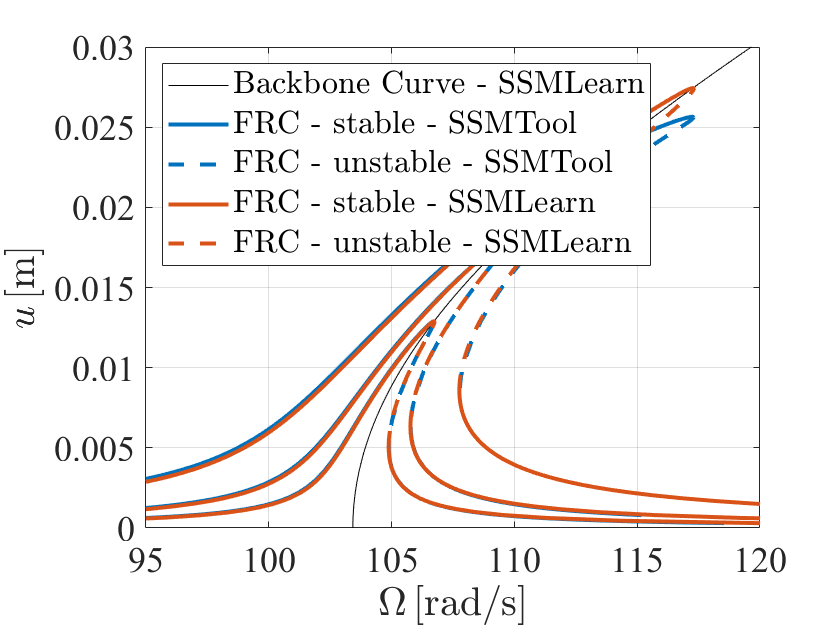

% Plot
figure; hold on; grid on; box on; colors = colororder;
plot(frq, amp,'k','DisplayName', 'Backbone Curve - SSMLearn')% $\mathcal{O}(7)$
for ii = 1:length(f_full)
   freq_i = FRC_full.(['F' num2str(ii)]).Freq;
   amp_i  = FRC_full.(['F' num2str(ii)]).Amp;  
   stab_i = FRC_full.(['F' num2str(ii)]).Stab;
   [~,pos] = find(abs(diff(stab_i))==1);
   h_i = plot(freq_i(1:pos(1)),amp_i(1:pos(1)),'Color',colors(1,:),'Linewidth',2,...
        'DisplayName', 'FRC - stable -  SSMTool');
   if length(pos)>1
       h_ii = plot(freq_i(pos(1)+1:pos(2)),amp_i(pos(1)+1:pos(2)),'--','Color',colors(1,:),'Linewidth',2,...
        'DisplayName', 'FRC - unstable -  SSMTool');
   h_iii = plot(freq_i(pos(2)+1:end),amp_i(pos(2)+1:end),'Color',colors(1,:),'Linewidth',2);
   h_iii.Annotation.LegendInformation.IconDisplayStyle = 'off'; 
   
   else
   h_ii = plot(freq_i(pos(1)+1:end),amp_i(pos(1)+1:end),'--','Color',colors(1,:),'Linewidth',2,...
        'DisplayName', 'FRC - unstable -  SSMTool');
   end
   if ii~= 1; h_i.Annotation.LegendInformation.IconDisplayStyle = 'off'; 
              h_ii.Annotation.LegendInformation.IconDisplayStyle = 'off'; end
end
for ii = 1:length(f_red)
   freq_i = FRC_data.(['F' num2str(ii)]).Freq;
   amp_i  = FRC_data.(['F' num2str(ii)]).Amp;  
   stab_i = FRC_data.(['F' num2str(ii)]).Stab;
   [~,pos] = find(abs(diff(stab_i))==1);
   h_i = plot(freq_i(1:pos(1)),amp_i(1:pos(1)),'Color',colors(2,:),'Linewidth',2,...
        'DisplayName', 'FRC - stable -  SSMLearn');
   h_ii = plot(freq_i(pos(1)+1:pos(2)),amp_i(pos(1)+1:pos(2)),'--','Color',colors(2,:),'Linewidth',2,...
        'DisplayName', 'FRC - unstable -  SSMLearn');
   h_iii = plot(freq_i(pos(2)+1:end),amp_i(pos(2)+1:end),'Color',colors(2,:),'Linewidth',2);
   h_iii.Annotation.LegendInformation.IconDisplayStyle = 'off';
   if ii~= 1; h_i.Annotation.LegendInformation.IconDisplayStyle = 'off'; 
              h_ii.Annotation.LegendInformation.IconDisplayStyle = 'off'; end
end
xlabel('$\Omega \, [$rad/s$]$','Interpreter','latex')
ylabel('$u \, [$m$]$','Interpreter','latex')
set(gca,'fontname','times')
set(gca,'fontsize',18)
legend('interpreter','latex','location','NW')
xlim([95 120])
ylim([0 0.03])